# System of Three Equations

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

Systems with three equations and three unknowns are more challenging to visualize, but the process for solving them with `fsolve` is the same.

In this activity, you'll visualize and solve the following system of equations.

*x^*2+*y^*2+*z^*2−3=0

3*x*−2*y*+*z*−2=0

sin(*x*)cos(*y*)+*z*=0

mySph = @(x, y, z) x.^2 + y.^2 + z.^2 - 3;
myPlane = @(x, y, z) 3*x - 2*y + z - 2;
myFun = @(x, y, z) sin(x).*cos(y) + z;

## Task 2

The `fimplicit3` function creates an implicit surface plot defined by *f*(*x*,*y*,*z*)=0.

`fimplicit3``(``f``)`

Similar to `plot`, you can specify the color of the surface with an additional input.

`fimplicit3``(``f``,``"r"``)`

You can make the surface transparent by setting the `"FaceAlpha"` property to a value between 0 and 1.

`fimplicit3``(``f``,``"r"``,``"FaceAlpha"``,``0.3``)`

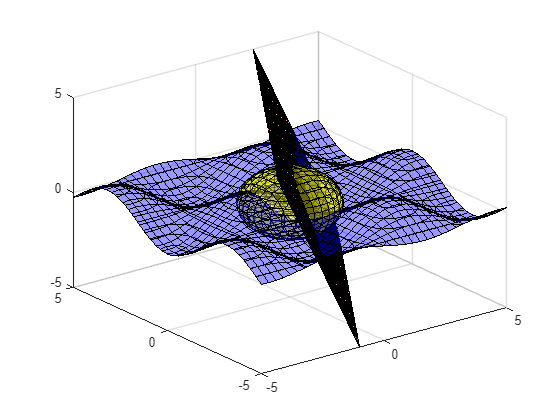

fimplicit3(mySph, "y", "FaceAlpha", 0.4)
hold on
fimplicit3(myPlane, "r", "FaceAlpha", 0.4)
fimplicit3(myFun, "b", "FaceAlpha", 0.4)
hold off

## Task 3

When you create a function handle `f` for a system with three equations and three variables, the vector input `w` is a 3 element vector made up of the variables *x*, *y*, and *z*. The definition of `f` returns a 3 element vector, with each element representing the corresponding equation in the system.

`f` `=` `@``(``w``)` `[` `f1``(``w``(``1``)``,``w``(``2``)``,``w``(``3``))``;`

           `f2``(``w``(``1``)``,``w``(``2``)``,``w``(``3``))``;`

           `f3``(``w``(``1``)``,``w``(``2``)``,``w``(``3``))` `]`

mySystem = @(w) [   mySph(w(1), w(2), w(3)); 
                    myPlane(w(1), w(2), w(3));  
                    myFun(w(1), w(2), w(3))];

## Task 4

w0 = [-0.5; -1.5; -0.5];
wRoot = fsolve(mySystem, w0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


wRoot =    -0.4358
   -1.6758
   -0.0442
